clc
clear all
close all

**Read Prices**

load myPrice_dt.mat
load array_prices

**Selection of a subset of Dates**

start_dt = datetime('01/01/2021', 'InputFormat', 'dd/MM/yyyy');
end_dt = datetime('01/01/2022', 'InputFormat', 'dd/MM/yyyy');

rng = timerange(start_dt, end_dt, 'closed');
subsample = myPrice_dt(rng, 1);
dates_ = subsample.Time;

**Calculate returns and Covariance Matrix**

LogRet = tick2ret(prices_val, 'Method', 'Continuous');
ExpRet = mean(LogRet);
V = cov(LogRet);

**Portfolio Optimization**

p = Portfolio('AssetList', assetNames);
p = setDefaultConstraints(p);
P = setAssetMoments(p, ExpRet, V);
pwgt = estimateFrontier(P, 100);
[pf_Risk, pf_Retn] = estimatePortMoments(P, pwgt);

**Compute Entropy**

N = 100;
EntropyEP = zeros(1, N);

for i = 1:N
    log_array = fillmissing(isfinite(log(pwgt(:,i))).*log(pwgt(:,i)), 'constant', 0);
    entropy = -pwgt(:,1)'*log_array;
    EntropyEP(i) = entropy;
end

**Plot Entropy**

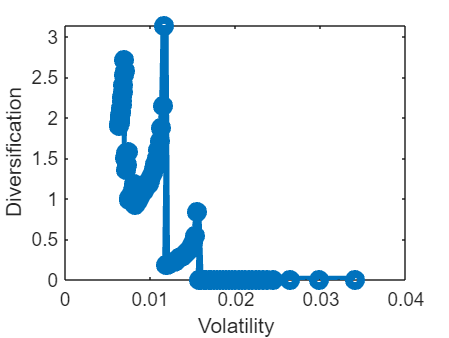

plot(pf_Risk, EntropyEP, '-o', 'LineWidth', 4)
xlabel('Volatility')
ylabel('Diversification')

**Compute max available entropy for that risk budget**

fun = @(x) x'*log(x);

x0 = rand(15,1);
x0 = x0./sum(x0);
lb = zeros(1,15);
ub = ones(1,15);
MaxEntropy = zeros(1,N);

for i = 1:N
    Aeq = ones(1,15);
    beq = 1;
    vol_i = pf_Risk(i);
    [w_opt, fval] = fmincon(fun, x0, [], [], Aeq, beq, lb, ub, @(x) nonlinConstr(x, V, vol_i));
    MaxEntropy(i) = -fval;
end


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<

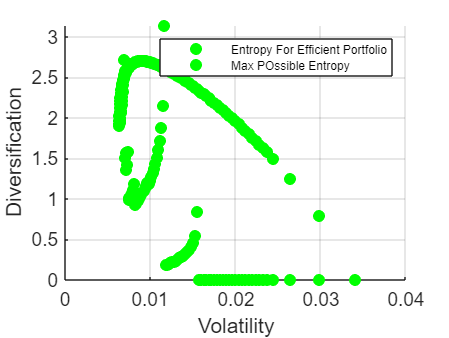


figure;
scatter(pf_Risk, EntropyEP, 'filled', 'g', 'LineWidth', 6)
hold on
scatter(pf_Risk, MaxEntropy, 'filled', 'g', 'LineWidth', 6)
grid on
legend('Entropy For Efficient Portfolio', 'Max POssible Entropy', 'FontSize', 6)
xlabel('Volatility')
ylabel('Diversification')